# Actividad #7

**Generación, Visualización y Almacenamiento de dinamico de Datasets CSV**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

## Descripción:

## Objetivos:

- **Comprender la generación de señales senoidales** a partir de parámetros ajustables como frecuencia, amplitud y fase.

- **Visualizar múltiples señales combinadas** (suma y resta) utilizando representaciones gráficas en función del tiempo.

- **Incorporar un sistema de TimeStamp** para alinear las señales con una referencia temporal precisa.

- **Construir datasets estructurados** en forma de tablas que integren señales y marcas de tiempo.

- **Exportar datasets generados en MATLAB** a archivos CSV utilizando funciones personalizadas.

- **Aplicar buenas prácticas de organización de proyectos** usando carpetas dedicadas (`src`, respaldo local) y funciones externas para modularizar el código.

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



## Desarrollo de la Actividad

#### **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window
addpath(genpath('./src'));

#### **Paso 2: Crear un codigo basico**

% Parámetros
f = 2;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1

simulationTime = 1×201 duration array
      0 sec   0.05 sec    0.1 sec   0.15 sec    0.2 sec   0.25 sec    0.3 sec   0.35 sec    0.4 sec   0.45 sec    0.5 sec   0.55 sec    0.6 sec   0.65 sec    0.7 sec   0.75 sec    0.8 sec   0.85 sec    0.9 sec   0.95 sec      1 sec   1.05 sec    1.1 sec   1.15 sec    1.2 sec   1.25 sec    1.3 sec   1.35 sec    1.4 sec   1.45 sec    1.5 sec   1.55 sec    1.6 sec   1.65 sec    1.7 sec   1.75 sec    1.8 sec   1.85 sec    1.9 sec   1.95 sec      2 sec   2.05 sec    2.1 sec   2.15 sec    2.2 sec   2.25 sec    2.3 sec   2.35 sec    2.4 sec   2.45 sec    2.5 sec   2.55 sec    2.6 sec   2.65 sec    2.7 sec   2.75 sec    2.8 sec   2.85 sec    2.9 sec   2.95 sec      3 sec   3.05 sec    3.1 sec   3.15 sec    3.2 sec   3.25 sec    3.3 sec   3.35 sec    3.4 sec   3.45 sec    3.5 sec   3.55 sec    3.6 sec   3.65 sec    3.7 sec   3.75 sec    3.8 sec   3.85 sec    3.9 sec   3.95 sec      4 sec   4.05 sec    4.1 sec   4.15 sec    4.2 sec   4.25 sec    4.3 sec   4.

fase1 = 0;      % Fase1

startTime = datetime
   13-Jun-2025 21:51:37


fase2 = 10;     % Fase2

timeStamp = 201×1 datetime array
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:37
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38
   13-Jun-2025 21:51:38


T = 10;          % Duración en segundos

ans = 'dd-MMM-uuuu HH:mm:ss'

fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)

ans =    201     1


fs = 20;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal
% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs)';
y2 = senal_senoidal(f,A2,fase2,T,fs)';
y3 = y1 + y2;
y4 = y1 - y2;

#### **Paso 3: TimeStamp (dd-MMM-yyyy HH:mm:ss)**

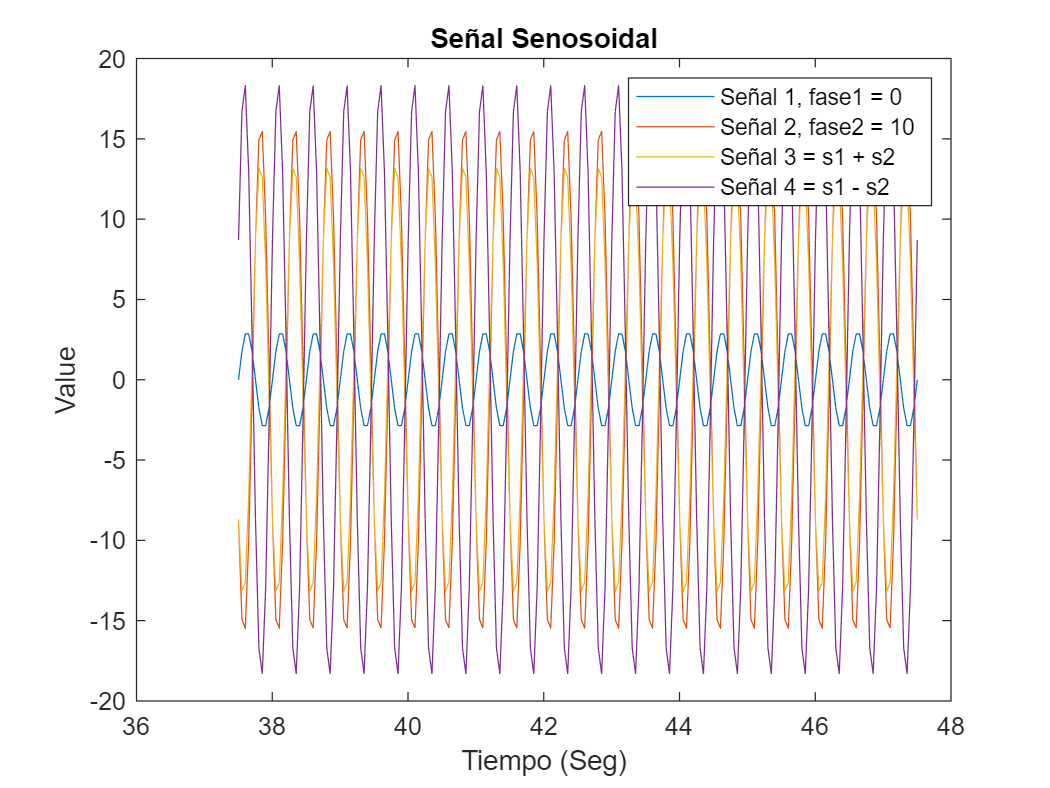

simulationTime = seconds(0:1/fs:T)
 startTime = datetime('now')
timeStamp = (startTime + simulationTime)'
timeStamp.Format
size(timeStamp) %filas, columnas

#### **Paso 4: Mostrar resultados con plot**

figure
plot(timeStamp.Second,y1) %Señal 1

VariableNames = 1×5 cell array
    {'TimeStamp'}    {'y1 = Sin1'}    {'y2 = Sin2'}    {'Y3 = y1 + y2'}    {'Y4 = y1 - y2'}


hold on
plot(timeStamp.Second,y2) %Señal 2

dataset = 201×5 table
         TimeStamp           y1 = Sin1     y2 = Sin2    Y3 = y1 + y2    Y4 = y1 - y2
    ____________________    ___________    _________    ____________    ____________

    13-Jun-2025 21:51:37              0     -8.7043        -8.7043         8.7043   
    13-Jun-2025 21:51:37         1.7634     -14.933         -13.17         16.696   
    13-Jun-2025 21:51:37         2.8532     -15.458        -12.605         18.311   
    13-Jun-2025 21:51:37         2.8532     -10.078        -7.2251         12.931   
    13-Jun-2025 21:51:37         1.7634    -0.84914        0.91421         2.6125   
    13-Jun-2025 21:51:37     3.6739e-16      8.7043         8.7043        -8.7043   
    13-Jun-2025 21:51:37        -1.7634      14.933          13.17        -16.696   
    13-Jun-2025 21:51:37        -2.8532   

plot(timeStamp.Second,y3) %Señal 3

ans = 1×5 cell array
    {'TimeStamp'}    {'y1 = Sin1'}    {'y2 = Sin2'}    {'Y3 = y1 + y2'}    {'Y4 = y1 - y2'}


plot(timeStamp.Second,y4) %Señal 4

ans = 201

title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 2, fase2 = 10", "Señal 3 = s1 + s2", "Señal 4 = s1 - s2")
hold off

#### **Paso 5: crear dataset usando tablas**

%cell array
VariableNames = {'TimeStamp', 'y1 = Sin1', 'y2 = Sin2', 'Y3 = y1 + y2'...
    , 'Y4 = y1 - y2'}
% Para la tabla el timeStamp debe ser una columna
dataset = table(timeStamp, y1, y2, y3, y4, 'VariableNames',VariableNames)
dataset.Properties.VariableNames
height(dataset)

#### Paso 6: Guardar los carchivos VSC en el computador

filename = 'dataset.csv';
fSave_dataset(filename,dataset)